clear;
clc;

% ii=1;
ii=3

ii = 3

ii=4;
number =int2str(ii);

wname = ['Perturb_Data New/Chamber',number,'W.csv'];
labels = categorical(["Fail","Working"]);
W=readmatrix(wname);

%Slice Data into chunks
chunkSize = 192; % Define the size of each chunk


numChunksW = ceil(size(W, 1) / chunkSize); % Calculate the number of chunks


chunksW = cell(numChunksW-1, 7); % Preallocate a cell array to hold the chunks
offset = 90; % offset at the start



%working case
for i = 1:numChunksW-1
    startIdx = offset+(i-1) * chunkSize + 1;
    endIdx = min(offset+(i * chunkSize), size(W, 1));
    for j = 1:6
        chunksW{i,j} = W(startIdx:endIdx, j);
    end
    chunksW{i,7}=labels(2);
end

% Visualize 10 chunks from each cell fail
% for i = 1:min(10, numChunksF)
%     figure;
%     plot(chunksF{i});
%     title(['Chunk ', int2str(i), ' from F']);
%     xlabel('Sample Index');
%     ylabel('Value');
% end
% 
% % Visualize 10 chunks from each cell working
% for i = 1:min(10, numChunksW)
%     figure;
%     plot(chunksW{i+60});
%     title(['Chunk ', int2str(i), ' from W']);
%     xlabel('Sample Index');
%     ylabel('Value');
% end


% Create a table containing 7 columns (6 signals + 1 label)

dataW = chunksW;
dataW = cell2table(dataW,'VariableNames',{'Ax','Ay','Az','Gx','Gy','Gz','label'});
sname = sprintf('Perturb_Data_Sim/SimFail_Full_Ch %d.mat',ii);
% sname = 'SimFail_Perturb_4__When_3_is_disconnected.mat';
dataf = load(sname);
chunksF =dataf. dataTable;
data = [dataW ;chunksF];
% data.Properties.VariableNames = {'Ax','Ay','Az','Gx','Gy','Gz','Label'};


%Extract top 10 features (Ranked by t-test)

features = GenerateTop10Features(data);

%Create test-train split
rng(0)
% idx = cvpartition(features.label); % Not holding out any data as testing on totally different data

featureTrain = features;

% load the testing data, generate the same features
data_test = load('Perturb_Data_Sim/SimFail_Perturb_4Working__When_3and5_are_disconnected.mat');
featureTest = GenerateTop10Features(data_test.dataTable);
% featureTest = features (idx.test,:);

featuresAfter = helperExtractLabeledData(featureTrain, ...
   "Working");
% featuresAfter= featuresAfter(1:40,:);

% take some of the working features and add it to test data
featuresWork= featureTrain(65:end,:);
featureTest =[featureTest;featuresWork];







featureDimension = 10;

% Define Fully Connected network layers
layers = [
    featureInputLayer(featureDimension,Normalization="zscore")
    fullyConnectedLayer(32)
    layerNormalizationLayer
    reluLayer
    dropoutLayer
    fullyConnectedLayer(8)
    layerNormalizationLayer
    reluLayer
    fullyConnectedLayer(32)
    layerNormalizationLayer
    reluLayer    
    fullyConnectedLayer(featureDimension)
    ];
% Set Training Options
% options = trainingOptions('adam', ...
%    'Plots', 'training-progress', ...
%    'Metrics', 'rmse', ...
%    'MiniBatchSize', 600,...
%    'MaxEpochs',120, ...   
%    'Verbose',false);

options = trainingOptions('adam', ...
   'Metrics', 'rmse', ...
   'MiniBatchSize', 20,...
   'MaxEpochs',120, ...   
   'Verbose',false);

net = trainnet(featuresAfter, featuresAfter, layers, "mse", options);

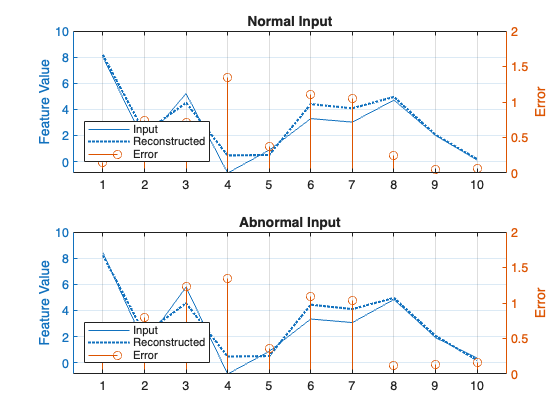

testNormal = featureTest(20, 2:end).Variables;
testAnomaly = featureTest(40, 2:end).Variables;

% Predict decoded signal for both
reconstructedNormal = predict(net,testNormal);
reconstructedAnomaly = predict(net,testAnomaly);

% Visualize
helperVisualizeModelBehavior(testNormal, testAnomaly, reconstructedNormal, reconstructedAnomaly)

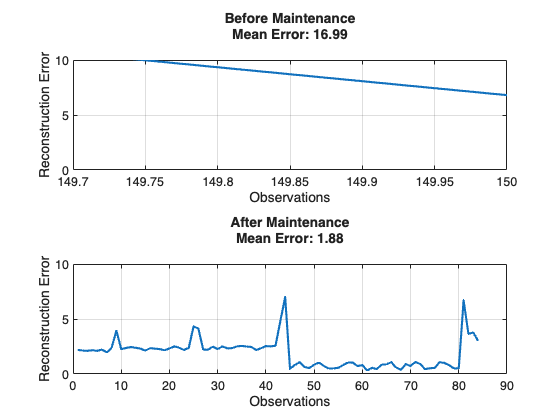

% Extract data before maintenance
XTestBefore = helperExtractLabeledData(featureTest, "Fail");

% Predict output before maintenance and calculate error
yHatBefore = minibatchpredict(net, XTestBefore, 'UniformOutput', true);
errorBefore = helperCalculateError(XTestBefore, yHatBefore);

% Extract data after maintenance
XTestAfter = helperExtractLabeledData(featureTest, "Working");

% Predict output after maintenance and calculate error
yHatAfter = minibatchpredict(net, XTestAfter, 'UniformOutput', true);
errorAfter = helperCalculateError(XTestAfter, yHatAfter);

helperVisualizeError(errorBefore, errorAfter);

XTestAll = helperExtractLabeledData(featureTest, "All");

yHatAll = minibatchpredict(net, XTestAll, 'UniformOutput', true);
errorAll = helperCalculateError(XTestAll, yHatAll);

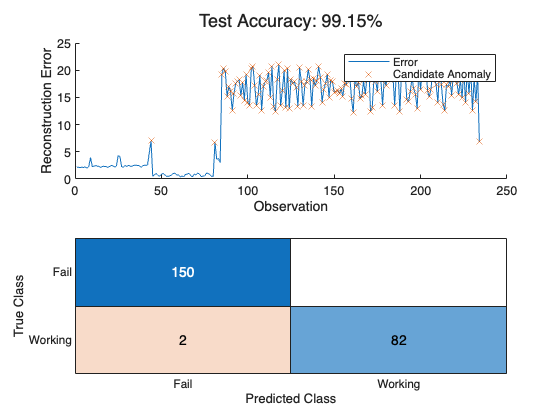

thresh = 0.55;
anomalies = errorAll > thresh*mean(errorAll);

helperVisualizeAnomalies(anomalies, errorAll, featureTest);